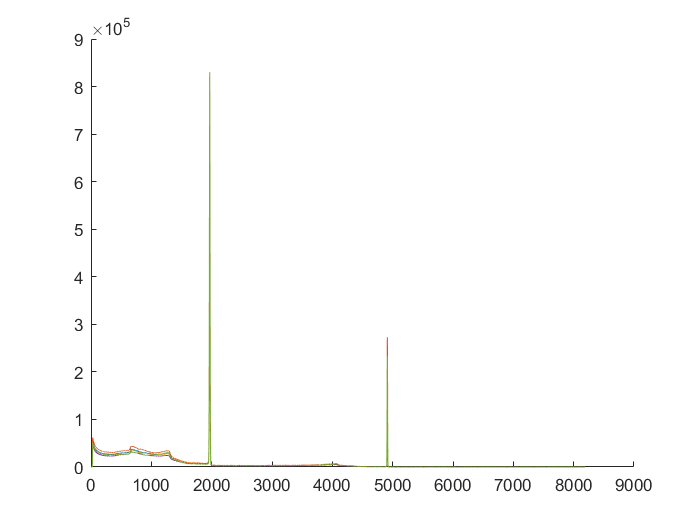

%% Finding Peaks at 511 and 1274 Peaks

% Read in DBAR Spectra Data and Assign to Array Variables
cd C:\Users\Admin\OneDrive\Documents\School\AFIT_Classes\Quarter_4\NENG_612\Lab_3\Data
DBAR_Data_1 = xlsread('MoZrO2_BL- 4hr - 20220831.xlsx');
DBAR_Data_2 = xlsread('MoZrO2_BR- 4hr - 20220831.xlsx');
DBAR_Data_3 = xlsread('MoZrO2_TL- 4hr - 20220831.xlsx');
DBAR_Data_4 = xlsread('MoZrO2_TR- 4hr - 20220831.xlsx');
DBAR_Data_5 = xlsread('AluminumFoil - 4hr - 20220824.xlsx');

% Plot Full Spectrum and Find Bin Range for Each Peak
Channels = 1:8190;
figure
hold on
plot(Channels,DBAR_Data_1)
plot(Channels,DBAR_Data_2)
plot(Channels,DBAR_Data_3)
plot(Channels,DBAR_Data_4)
plot(Channels,DBAR_Data_5)
hold off

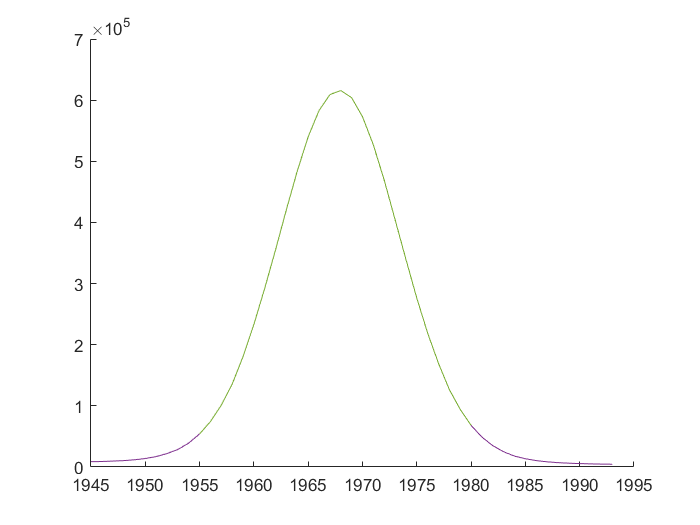


%Plot Each 511 Peak 
Channels_511_1 = 1950:1990; % Identified Bin Range from Above Plots
Counts_511_1 = DBAR_Data_1(Channels_511_1); % Identified Count Range from Above Plots
Channels_511_2 = 1950:1984; 
Counts_511_2 = DBAR_Data_1(Channels_511_2);
Channels_511_3 = 1947:1989;
Counts_511_3 = DBAR_Data_1(Channels_511_3);
Channels_511_4 = 1945:1993;
Counts_511_4 = DBAR_Data_1(Channels_511_4);
Channels_511_5 = 1955:1980;
Counts_511_5 = DBAR_Data_1(Channels_511_5);

figure
hold on
plot(Channels_511_1,Counts_511_1)
plot(Channels_511_2,Counts_511_2)
plot(Channels_511_3,Counts_511_3)
plot(Channels_511_4,Counts_511_4)
plot(Channels_511_5,Counts_511_5)
hold off

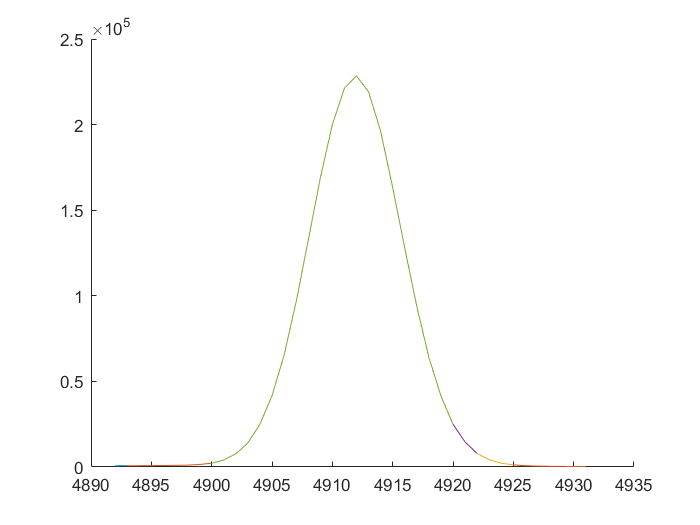


% Plot Each 1274 Peak 
Channels_1274_1 = 4892:4929; % Identified Bin Range from Above Plots
Counts_1274_1 = DBAR_Data_1(Channels_1274_1); % Identified Count Range from Above Plots
Channels_1274_2 = 4893:4931;
Counts_1274_2 = DBAR_Data_1(Channels_1274_2);
Channels_1274_3 = 4900:4925;
Counts_1274_3 = DBAR_Data_1(Channels_1274_3);
Channels_1274_4 = 4902:4922;
Counts_1274_4 = DBAR_Data_1(Channels_1274_4);
Channels_1274_5 = 4900:4920;
Counts_1274_5 = DBAR_Data_1(Channels_1274_5);

figure
hold on
plot(Channels_1274_1,Counts_1274_1)
plot(Channels_1274_2,Counts_1274_2)
plot(Channels_1274_3,Counts_1274_3)
plot(Channels_1274_4,Counts_1274_4)
plot(Channels_1274_5,Counts_1274_5)
hold off


% Intructions
    % Download Curve Fitting App
    % App Tab > Curve Fitting > 
        % Fit Name: 'Your Choice', X data: Channel Range, Y data: Count Range, Z data: (none), Weights: (none)
        % Gaussian, Number of terms: 3, Fit Options Tab: Change all 'a' value lower bouds from -INF to 0
    % Fit Tab: Save to Workspace

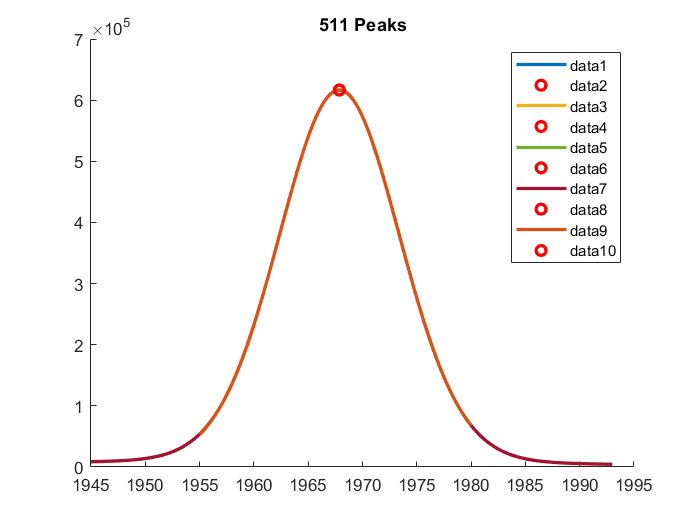

%% Callibrating Bins and converting to Energy

% Defining Channel Ranges
x_1 = Channels_511_1(1):.001:Channels_511_1(end); % Defined Channel Range from original spectrum with finer step size
y_1 = Channels_1274_1(1):.001:Channels_1274_1(end); % Defined Channel Range from original spectrum with finer step size
x_2 = Channels_511_2(1):.001:Channels_511_2(end); % Defined Channel Range from original spectrum with finer step size
y_2 = Channels_1274_2(1):.001:Channels_1274_2(end); % Defined Channel Range from original spectrum with finer step size
x_3 = Channels_511_3(1):.001:Channels_511_3(end); % Defined Channel Range from original spectrum with finer step size
y_3 = Channels_1274_3(1):.001:Channels_1274_3(end); % Defined Channel Range from original spectrum with finer step size
x_4 = Channels_511_4(1):.001:Channels_511_4(end); % Defined Channel Range from original spectrum with finer step size
y_4 = Channels_1274_4(1):.001:Channels_1274_4(end); % Defined Channel Range from original spectrum with finer step size
x_5 = Channels_511_5(1):.001:Channels_511_5(end); % Defined Channel Range from original spectrum with finer step size
y_5 = Channels_1274_5(1):.001:Channels_1274_5(end); % Defined Channel Range from original spectrum with finer step size

% Finding Calibration Points
[mY_1,mI_1] = max(Gaussian_511_1(x_1)); % X,Y Coordinate of Gaussian Centroid
[mY_2,mI_2] = max(Gaussian_511_2(x_2)); % X,Y Coordinate of Gaussian Centroid
[mY_3,mI_3] = max(Gaussian_511_3(x_3)); % X,Y Coordinate of Gaussian Centroid
[mY_4,mI_4] = max(Gaussian_511_4(x_4)); % X,Y Coordinate of Gaussian Centroid
[mY_5,mI_5] = max(Gaussian_511_5(x_5)); % X,Y Coordinate of Gaussian Centroid
[nY_1,nI_1] = max(Gaussian_1274_1(y_1)); % X,Y Coordinate of Gaussian Centroid
[nY_2,nI_2] = max(Gaussian_1274_2(y_2)); % X,Y Coordinate of Gaussian Centroid
[nY_3,nI_3] = max(Gaussian_1274_3(y_3)); % X,Y Coordinate of Gaussian Centroid
[nY_4,nI_4] = max(Gaussian_1274_4(y_4)); % X,Y Coordinate of Gaussian Centroid
[nY_5,nI_5] = max(Gaussian_1274_5(y_5)); % X,Y Coordinate of Gaussian Centroid

% Plotting Gaussian Curve overlaid with Centroid Point
figure
hold on
plot(x_1,Gaussian_511_1(x_1),x_1(mI_1),mY_1,'or','LineWidth',2)
plot(x_2,Gaussian_511_2(x_2),x_2(mI_2),mY_2,'or','LineWidth',2)
plot(x_3,Gaussian_511_3(x_3),x_3(mI_3),mY_3,'or','LineWidth',2)
plot(x_4,Gaussian_511_4(x_4),x_4(mI_4),mY_4,'or','LineWidth',2)
plot(x_5,Gaussian_511_5(x_5),x_5(mI_5),mY_5,'or','LineWidth',2)
legend() 
title('511 Peaks')
hold off

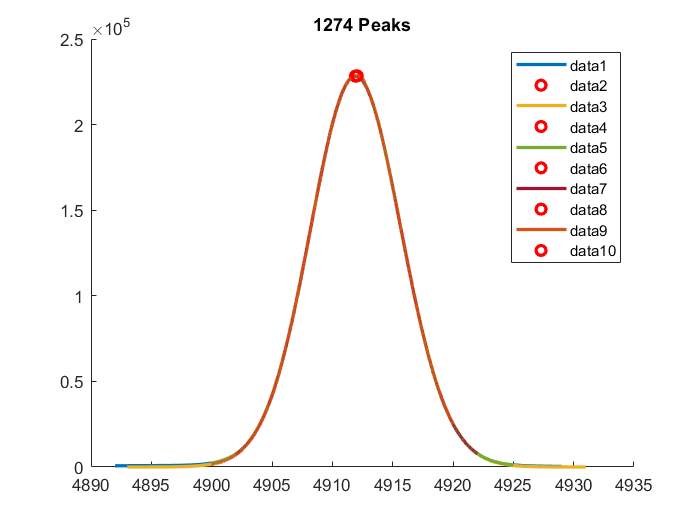


% Plotting Gaussian Curve overlaid with Centroid Point
figure
hold on
plot(y_1,Gaussian_1274_1(y_1),y_1(nI_1),nY_1,'or','LineWidth',2)
plot(y_2,Gaussian_1274_2(y_2),y_2(nI_2),nY_2,'or','LineWidth',2)
plot(y_3,Gaussian_1274_3(y_3),y_3(nI_3),nY_3,'or','LineWidth',2)
plot(y_4,Gaussian_1274_4(y_4),y_4(nI_4),nY_4,'or','LineWidth',2)
plot(y_5,Gaussian_1274_5(y_5),y_5(nI_5),nY_5,'or','LineWidth',2)
legend() 
title('1274 Peaks')
hold off

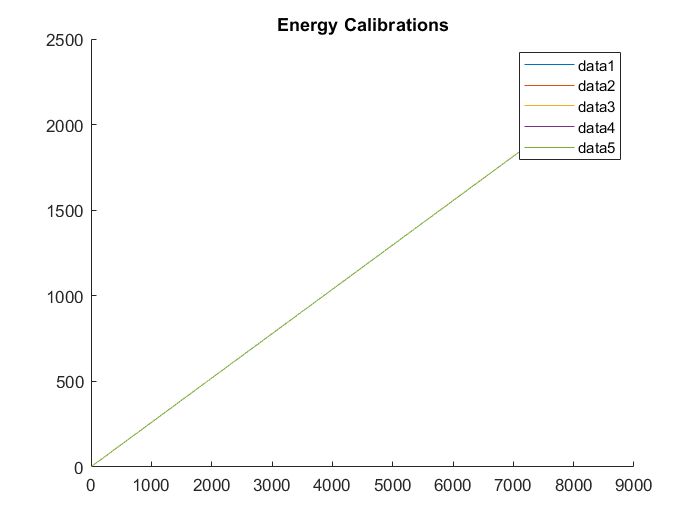

%% Calibrating Spectra by Energy 

Calibration_Slope_1 = (1274-511)./(y_1(nI_1)-x_1(mI_1));
Calibration_Slope_2 = (1274-511)./(y_2(nI_2)-x_2(mI_2));
Calibration_Slope_3 = (1274-511)./(y_3(nI_3)-x_3(mI_3));
Calibration_Slope_4 = (1274-511)./(y_4(nI_4)-x_4(mI_4));
Calibration_Slope_5 = (1274-511)./(y_5(nI_5)-x_5(mI_5));

Calibration_Intercept_511_1 = 511 - Calibration_Slope_1*x_1(mI_1);
Calibration_Intercept_511_2 = 511 - Calibration_Slope_2*x_2(mI_2);
Calibration_Intercept_511_3 = 511 - Calibration_Slope_3*x_3(mI_3);
Calibration_Intercept_511_4 = 511 - Calibration_Slope_4*x_4(mI_4);
Calibration_Intercept_511_5 = 511 - Calibration_Slope_5*x_5(mI_5);

Calibration_Intercept_1274_1 = 1274 - Calibration_Slope_1*y_1(nI_1);
Calibration_Intercept_1274_2 = 1274 - Calibration_Slope_2*y_2(nI_2);
Calibration_Intercept_1274_3 = 1274 - Calibration_Slope_3*y_3(nI_3);
Calibration_Intercept_1274_4 = 1274 - Calibration_Slope_4*y_4(nI_4);
Calibration_Intercept_1274_5 = 1274 - Calibration_Slope_5*y_5(nI_5);

Calibration_Intercept_1 = (Calibration_Intercept_511_1+Calibration_Intercept_1274_1)/2;
Calibration_Intercept_2 = (Calibration_Intercept_511_2+Calibration_Intercept_1274_2)/2;
Calibration_Intercept_3 = (Calibration_Intercept_511_3+Calibration_Intercept_1274_3)/2;
Calibration_Intercept_4 = (Calibration_Intercept_511_4+Calibration_Intercept_1274_4)/2;
Calibration_Intercept_5 = (Calibration_Intercept_511_5+Calibration_Intercept_1274_5)/2;

Energy_1 = Calibration_Slope_1.*Channels + Calibration_Intercept_1;
Energy_2 = Calibration_Slope_2.*Channels + Calibration_Intercept_2;
Energy_3 = Calibration_Slope_3.*Channels + Calibration_Intercept_3;
Energy_4 = Calibration_Slope_4.*Channels + Calibration_Intercept_4;
Energy_5 = Calibration_Slope_5.*Channels + Calibration_Intercept_5;

figure
hold on
plot(Channels,Energy_1)
plot(Channels,Energy_2)
plot(Channels,Energy_3)
plot(Channels,Energy_4)
plot(Channels,Energy_5)
legend() 
title('Energy Calibrations')
hold off

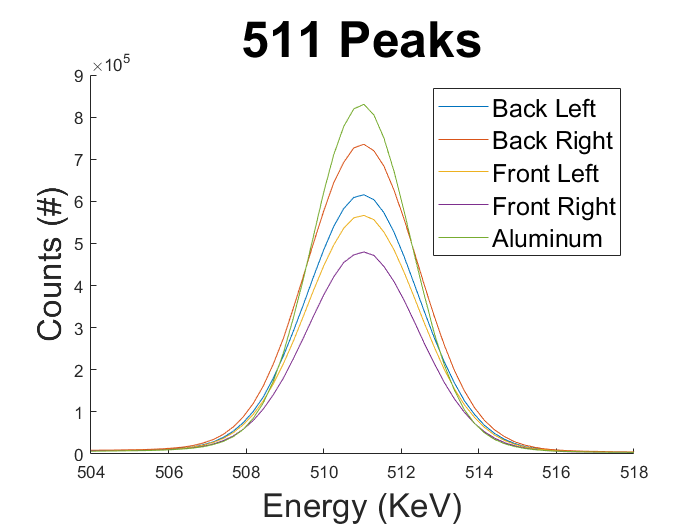

figure
hold on
plot(Energy_1,DBAR_Data_1);
plot(Energy_2,DBAR_Data_2);
plot(Energy_3,DBAR_Data_3);
plot(Energy_4,DBAR_Data_4);
plot(Energy_5,DBAR_Data_5);
hold off
legend('Back Left', 'Back Right', 'Front Left', 'Front Right','Aluminum','FontSize',15)
title('511 Peaks','FontSize',30)
xlabel('Energy (KeV)','FontSize',20)
ylabel('Counts (#)','FontSize',20)
xlim([504,518])

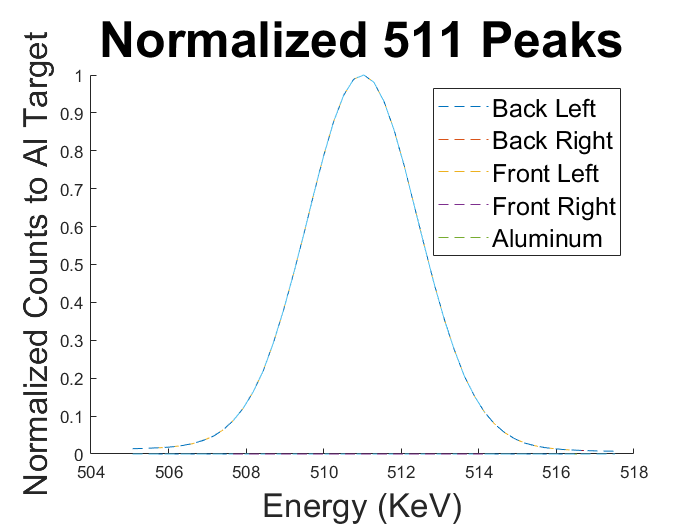


figure
hold on
plot(Energy_1(Channels_511_1),Counts_511_1/Counts_511_5,'--');
plot(Energy_2(Channels_511_2),Counts_511_2/Counts_511_5,'--');
plot(Energy_3(Channels_511_3),Counts_511_3/Counts_511_5,'--');
plot(Energy_4(Channels_511_4),Counts_511_4/Counts_511_5,'--');
plot(Energy_5(Channels_511_5),Counts_511_5/Counts_511_5,'--');
hold off
legend('Back Left', 'Back Right', 'Front Left', 'Front Right','Aluminum','FontSize',15)
title('Normalized 511 Peaks','FontSize',30)
xlabel('Energy (KeV)','FontSize',20)
ylabel('Normalized Counts to Al Target','FontSize',20)

## Calculating S and W Parameters

F1 = griddedInterpolant(Energy_1,DBAR_Data_1);
fun1 = @(t) F1(t);
S1 = integral(fun1, Energy_1(510), Energy_1(512))/integral(fun1, Energy_1(506), Energy_1(516));
sigmaS1=1/max(DBAR_Data_1)*sqrt(S1*(S1+1));
W1 = integral(fun1, Energy_1(513), Energy_1(515))/integral(fun1, Energy_1(506), Energy_1(516));
sigmaW1=1/max(DBAR_Data_1)*sqrt(W1*(W1+1));
F2 = griddedInterpolant(Energy_2,DBAR_Data_2);
fun2 = @(t) F2(t);
S2 = integral(fun2, Energy_2(510), Energy_2(512))/integral(fun2, Energy_2(506), Energy_2(516));
sigmaS2=1/max(DBAR_Data_2)*sqrt(S2*(S2+1));
W2 = integral(fun2, Energy_2(513), Energy_2(515))/integral(fun2, Energy_2(506), Energy_2(516));
sigmaW2=1/max(DBAR_Data_2)*sqrt(W2*(W2+1));
F3 = griddedInterpolant(Energy_3,DBAR_Data_3);
fun3 = @(t) F3(t);
S3 = integral(fun3, Energy_3(510), Energy_3(512))/integral(fun3, Energy_3(506), Energy_3(516));
sigmaS3=1/max(DBAR_Data_3)*sqrt(S3*(S3+1));
W3 = integral(fun3, Energy_3(513), Energy_3(515))/integral(fun3, Energy_3(506), Energy_3(516));
sigmaW3=1/max(DBAR_Data_3)*sqrt(W3*(W3+1));
F4 = griddedInterpolant(Energy_4,DBAR_Data_4);
fun4 = @(t) F4(t);
S4 = integral(fun4, Energy_4(510), Energy_4(512))/integral(fun4, Energy_4(506), Energy_4(516));
sigmaS4=1/max(DBAR_Data_4)*sqrt(S4*(S4+1));
W4 = integral(fun4, Energy_4(513), Energy_4(515))/integral(fun4, Energy_4(506), Energy_4(516));
sigmaW4=1/max(DBAR_Data_4)*sqrt(W4*(W4+1));
F5 = griddedInterpolant(Energy_5,DBAR_Data_5);
fun5 = @(t) F5(t);
S5 = integral(fun5, Energy_5(510), Energy_5(512))/integral(fun5, Energy_5(506), Energy_5(516));
sigmaS5=1/max(DBAR_Data_5)*sqrt(S5*(S5+1));
W5 = integral(fun5, Energy_5(513), Energy_5(515))/integral(fun5, Energy_5(506), Energy_5(516));
sigmaW5=1/max(DBAR_Data_5)*sqrt(W5*(W5+1));
fprintf('%0.4f %0.4d %0.4f %0.4d\n',S1,sigmaS1,W1,sigmaW1)

0.1999 7.9543e-07 0.2001 7.9575e-07


fprintf('%0.4f %0.4d %0.4f %0.4d\n',S2,sigmaS2,W2,sigmaW2)

0.2003 6.6664e-07 0.1999 6.6594e-07


fprintf('%0.4f %0.4d %0.4f %0.4d\n',S3,sigmaS3,W3,sigmaW3)

0.2001 8.6518e-07 0.2001 8.6501e-07


fprintf('%0.4f %0.4d %0.4f %0.4d\n',S4,sigmaS4,W4,sigmaW4)

0.1997 1.0200e-06 0.2001 1.0215e-06


fprintf('%0.4f %0.4d %0.4f %0.4d\n',S5,sigmaS5,W5,sigmaW5)

0.2007 5.9118e-07 0.2000 5.8990e-07
